try
    fclose(instrfindall);
    delete(instrfindall);
catch
end
clear;
input("Turn off the Mojave then hit enter.");
mojave = robot;

mojave.set_speed(-1);
input("You may now turn on the Mojave.");

addpath brainwaves
oarbiter = arbiter(@() april_tag_wave(), linspace(0, 1, 7), linspace(-30, 30, 7));

tic;
while toc < 30
    [v, w] = oarbiter.arbitrate();
    mojave.set_speed(v);
    mojave.steer(w);
end

cam = webcam(1);
cam_figure = figure('Name', 'Camera Preview');
preview(cam);
vel_figure = figure('Name', 'Velocity Brainwave');
ang_figure = figure('Name', 'Steering Brainwave');

addpath brainwaves\
oarbiter = arbiter(@() april_tag_wave(), linspace(0, 1, 7), linspace(-30, 30, 7));
tic;
tcurrent = 0;
while true
    img = snapshot(cam);
    img = rot90(img, 3);
    [ids, corners, poses] = readAprilTag(img, 'tag36h11', cameraParams.Intrinsics, 164);
    if isempty(ids)
        continue;
    end
    tags = april_tag(ids, corners, poses);

    [v, w] = oarbiter.arbitrate();
    [vwave, wwave] = april_tag_wave();
    figure(vel_figure);
    plot(oarbiter.vel_result_vec, vwave);
    figure(ang_figure);
    plot(oarbiter.ang_result_vec, wwave);
    tcurrent = toc;
end

mojave = robot

Invalid default value for property 'arduino' in class 'robot':
MATLAB connection to Nano3 at COM9 exists in your workspace. To create a new connection, clear the existing
object.

mojave.lidar_setup()

ans =   robot with properties:

        robot_cam: [1×1 webcam]
    camera_params: [1×1 cameraParameters]
          arduino: [1×1 arduino]
            lidar: [1×1 serial]
           ir_vec: ["A1"    "A2"    "A3"    "A6"]
        sonar_vec: ["A0"    "A7"]
          lsm_obj: []
              neo: []
      steer_servo: [1×1 arduinoio.Servo]
         throttle: [1×1 arduinoio.Servo]
        pan_servo: [1×1 arduinoio.Servo]
        cam_angle: 0
       tilt_servo: [1×1 arduinoio.Servo]


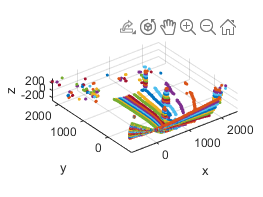

ans =   robot with properties:

        robot_cam: [1×1 webcam]
    camera_params: [1×1 cameraParameters]
          arduino: [1×1 arduino]
            lidar: [1×1 serial]
           ir_vec: ["A1"    "A2"    "A3"    "A6"]
        sonar_vec: ["A0"    "A7"]
          lsm_obj: []
              neo: []
      steer_servo: [1×1 arduinoio.Servo]
         throttle: [1×1 arduinoio.Servo]
        pan_servo: [1×1 arduinoio.Servo]
        cam_angle: 0
       tilt_servo: [1×1 arduinoio.Servo]


mojave.lidar_scan_3d()